% Exercise 2
% Q1 & Q2: Class parameters from Exercise 1

% Baseline means and covariances
mu_a = [0, 4, 7];
mu_b = [10, 5, 5];
mu_c = [-2, -5, -5];

covm_a = [6.5 2.1651 1.25;
    2.1651 5.125 2.3816;
    1.25 2.3816 2.375];
covm_b = [3.0184 0.4331 -1.4481;
    0.4331 0.9436 -0.6456;
    -1.4481 -0.6456 1.288];
covm_c = [6.8928 -1.375 3.1945;
    -1.375 3.3572 0.6945;
    3.1945 0.6945 3.75];

% Grid parameters for boundary computation
Vaxis = [-15, 15];
Num = 200; % 200^3 regular grid points


Q2: We load the plotting functions from Activity 1 and play with the means and covariances of the three classes, assessing how they affect the class boundaries.

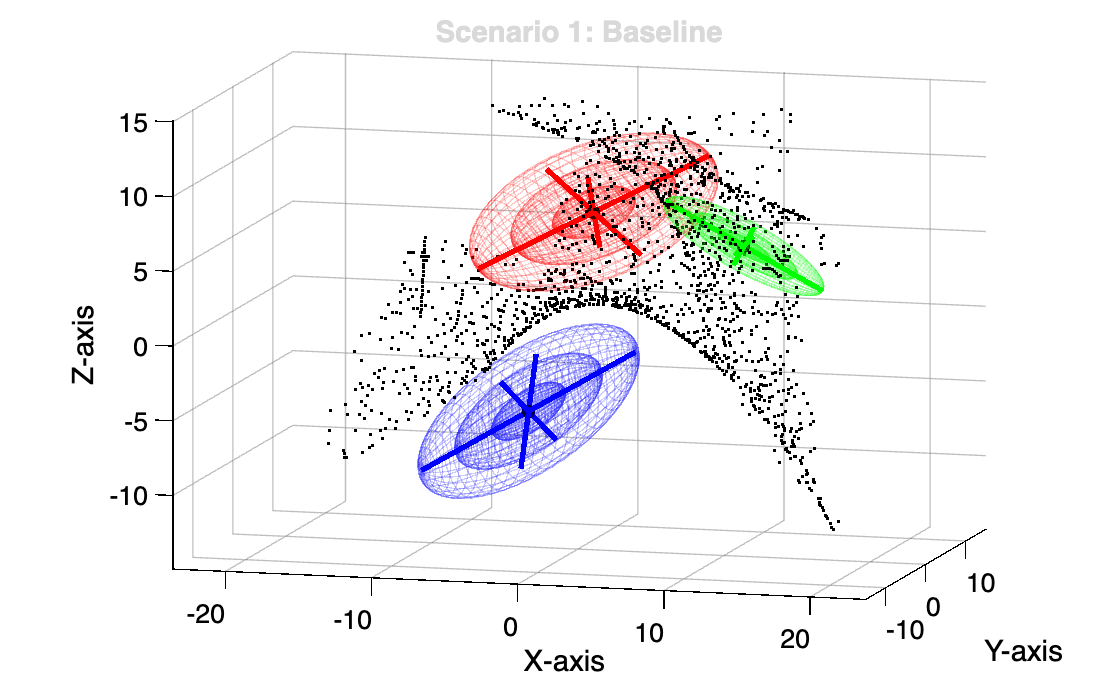

% Scenario 1: Baseline - original means and covariances from Exercise 1
plotScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, 'Scenario 1: Baseline', Vaxis, Num);


function plotClassEllipsoids(mu, covm, color)
    % 1. Get eigenvalues (D) and eigenvectors (V)
    [V, D] = eig(covm);
    
    % The lengths of the semi-axes are the square roots of the eigenvalues
    % (which represent 1 standard deviation along the principal axes)
    radii_1std = sqrt(diag(D))';
    
    % Define the standard deviations we want to plot
    stdDevs = [1, 2, 3];
    
    % Loop through 1, 2, and 3 standard deviations
    for sd = stdDevs
        % Scale the base radii by the standard deviation level
        current_radii = radii_1std * sd;
        
        % Generate a standard axis-aligned ellipsoid at the origin
        % syntax: ellipsoid(xc, yc, zc, xr, yr, zr, n)
        [X, Y, Z] = ellipsoid(0, 0, 0, current_radii(1), current_radii(2), current_radii(3), 30);
        
        % Rotate and translate the ellipsoid points
        % Pack points into an N x 3 matrix
        pts = [X(:), Y(:), Z(:)];
        
        % Apply rotation (V) and shift to the mean (mu)
        rotated_pts = (pts * V') + mu;
        
        % Reshape back into surface grids for plotting
        X_rot = reshape(rotated_pts(:,1), size(X));
        Y_rot = reshape(rotated_pts(:,2), size(Y));
        Z_rot = reshape(rotated_pts(:,3), size(Z));
        
        % Plot the ellipsoid surface with transparency (Alpha)
        mesh(X_rot, Y_rot, Z_rot, 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.2);
    end
    
    % 2. Plot the Principal Axes (drawn out to 3 standard deviations)
    for d = 1:3
        % Direction vector of the principal axis
        axis_direction = V(:, d)'; 
        % Half-length of the axis at 3 standard deviations
        half_length = radii_1std(d) * 3; 
        
        % Calculate start and end points for the line
        p_start = mu - half_length * axis_direction;
        p_end = mu + half_length * axis_direction;
        
        % Draw the principal axis line using matlab's line() function
        line([p_start(1), p_end(1)], ...
             [p_start(2), p_end(2)], ...
             [p_start(3), p_end(3)], ...
             'Color', color, 'LineWidth', 2);
    end
    
    % Plot the center mean point
    plot3(mu(1), mu(2), mu(3), 'k.', 'MarkerSize', 15);
end

% Compute Bayes decision boundary points for three Gaussian classes
function [bAB, bAC, bCB] = computeBoundaries(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num)
    grid_points = vol3D(Vaxis, Num);

    covm_a_inv = inv(covm_a);
    covm_b_inv = inv(covm_b);
    covm_c_inv = inv(covm_c);

    covm_a_det = det(covm_a);
    covm_b_det = det(covm_b);
    covm_c_det = det(covm_c);

    cp_a = grid_points - mu_a;
    cp_b = grid_points - mu_b;
    cp_c = grid_points - mu_c;

    % Bayesian discriminant scores (equal priors)
    g_a = -0.5 * sum((cp_a * covm_a_inv) .* cp_a, 2) - 0.5 * log(covm_a_det) + log(1/3);
    g_b = -0.5 * sum((cp_b * covm_b_inv) .* cp_b, 2) - 0.5 * log(covm_b_det) + log(1/3);
    g_c = -0.5 * sum((cp_c * covm_c_inv) .* cp_c, 2) - 0.5 * log(covm_c_det) + log(1/3);

    epsilon = 0.01;
    bAB = grid_points((abs(g_a - g_b) < epsilon) & (g_a > g_c) & (g_b > g_c), :);
    bAC = grid_points((abs(g_a - g_c) < epsilon) & (g_a > g_b) & (g_c > g_b), :);
    bCB = grid_points((abs(g_b - g_c) < epsilon) & (g_b > g_a) & (g_c > g_a), :);
end

% Compute boundaries and produce a labelled 3-D plot
function plotScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, titleStr, Vaxis, Num)
    [bAB, bAC, bCB] = computeBoundaries(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c, Vaxis, Num);
    colors = {'r', 'g', 'b'};
    figure;
    set(gcf, 'Color', 'w');
    clf; hold on; grid on; axis equal; view(3);
    % Force white axes regardless of MATLAB theme
    set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k');
    plotClassEllipsoids(mu_a, covm_a, colors{1});
    plotClassEllipsoids(mu_b, covm_b, colors{2});
    plotClassEllipsoids(mu_c, covm_c, colors{3});
    plot3(bAB(:,1), bAB(:,2), bAB(:,3), 'k.', 'MarkerSize', 1);
    plot3(bAC(:,1), bAC(:,2), bAC(:,3), 'k.', 'MarkerSize', 1);
    plot3(bCB(:,1), bCB(:,2), bCB(:,3), 'k.', 'MarkerSize', 1);
    title(titleStr);
    xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis');
    hold off;
end

Next we experiment with different combinations of mu and covariance to see how the class boundaries change.

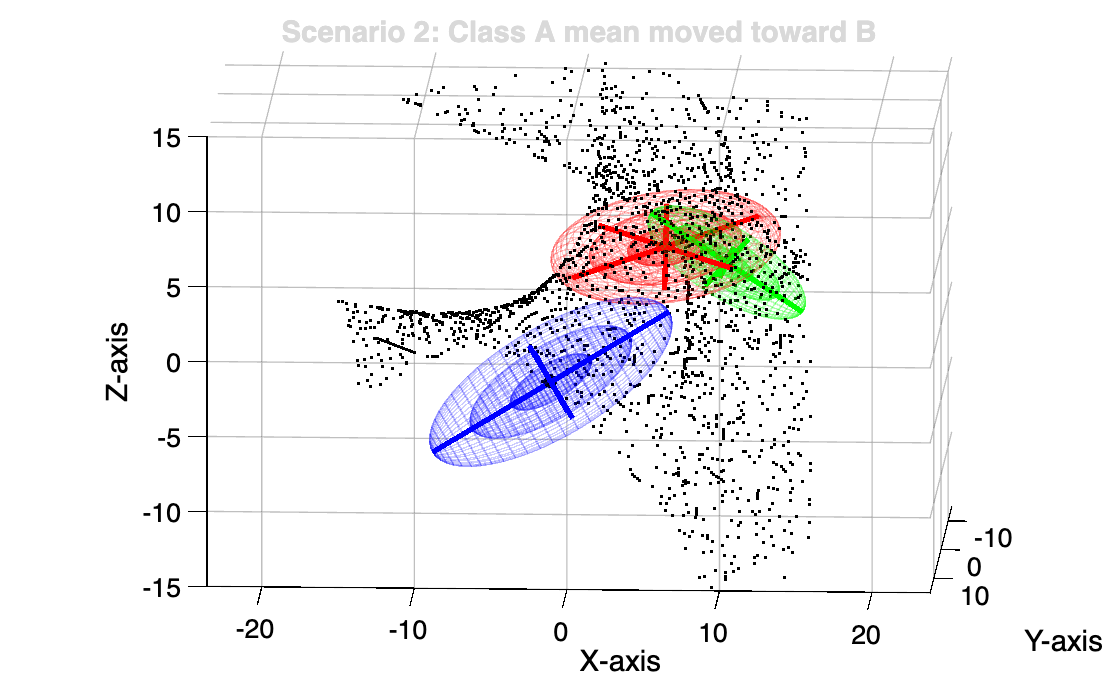

% Scenario 2: Move class A closer to class B (means approach each other)
mu_a2 = [6, 5, 6];
plotScenario(mu_a2, covm_a, mu_b, covm_b, mu_c, covm_c, 'Scenario 2: Class A mean moved toward B', Vaxis, Num);

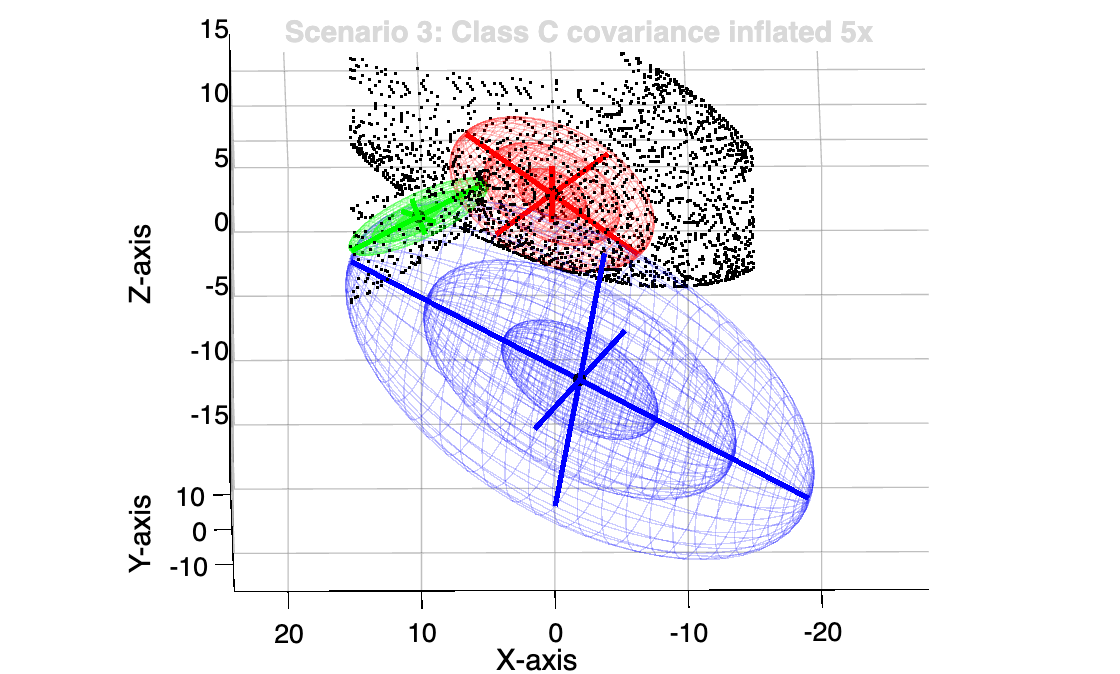


% Scenario 3: Inflate class C covariance (spreads C's distribution)
covm_c3 = covm_c * 5;
plotScenario(mu_a, covm_a, mu_b, covm_b, mu_c, covm_c3, 'Scenario 3: Class C covariance inflated 5x', Vaxis, Num);

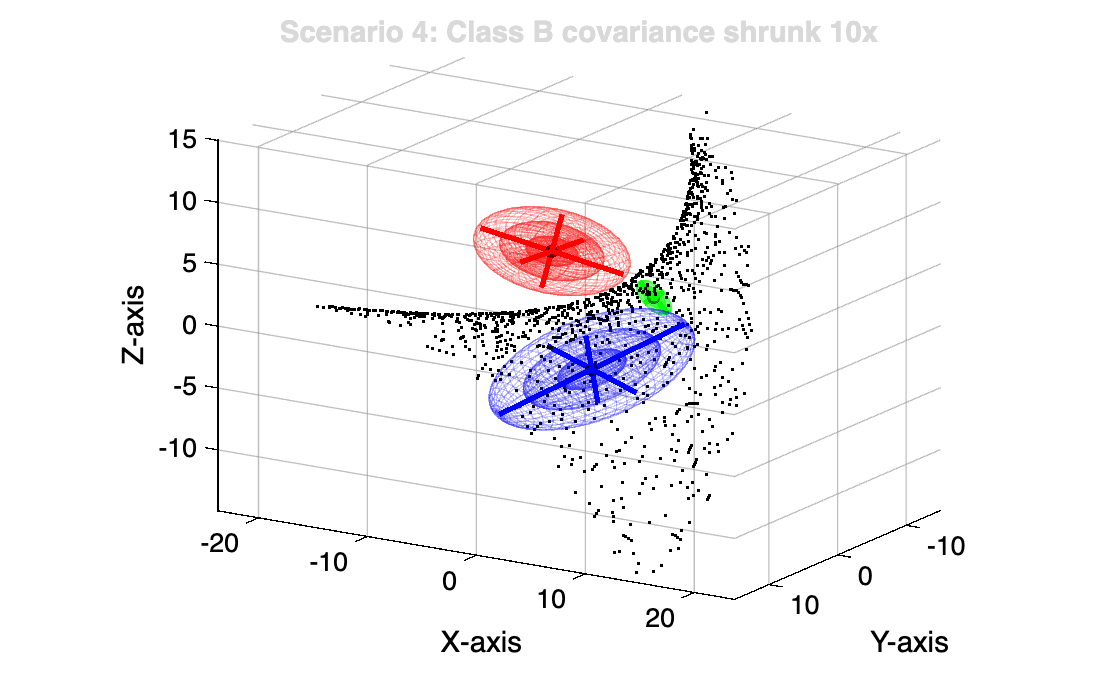


% Scenario 4: Shrink class B covariance
covm_b4 = covm_b * 0.1;
plotScenario(mu_a, covm_a, mu_b, covm_b4, mu_c, covm_c, 'Scenario 4: Class B covariance shrunk 10x', Vaxis, Num);

Q3: We identify which class covariance produces the most sensitive decision boundaries by looking at the eigenvalue ratios. Class B has a 16:1 max/min eigenvalue ratio - the largest of the three classes. Its smallest eigenvalue (0.25) causes high sensitivity. This is because the Bayesian decision boundaries depend on the inverse of the covariance, whose eigenvalues are the reciprocals of the covariance's eigenvalues. This in turn means that a small change to a small eigenvalue causes a disproportionately large change in the inverse of the covariance, which directly drives the discriminant function and hence the decision boundary shape. We demonstrate this with two examples: nudging that eigenvalue up and down by 20%. To illustrate: applying the same absolute change of +0.05 to the smallest eigenvalue (0.25 to 0.30) changes the corresponding inverse of the covariance from 4.00 to 3.33 - a shift of 0.6t7. The same change applied to the largest eigenvalue (4.00 to 4.05) changes the inverse of the covariance from 0.250 to 0.247 - a shift of just 0.003. So the same change applied to a small eigenvalue rather than a large one, produces over two hundred times the effect on the inverse of the covariance.

% Q3: Eigendecomposition analysis - identifying sensitivity

% Eigendecomposition of each class covariance
[V_a, D_a] = eig(covm_a);
[V_b, D_b] = eig(covm_b);
[V_c, D_c] = eig(covm_c);

eigs_a = diag(D_a);
eigs_b = diag(D_b);
eigs_c = diag(D_c);

fprintf('=== Eigenvalue Analysis ===\n\n');

=== Eigenvalue Analysis ===



fprintf('Class A eigenvalues: %.4f  %.4f  %.4f   (max/min ratio = %.1f)\n', ...
    eigs_a(1), eigs_a(2), eigs_a(3), eigs_a(3)/eigs_a(1));

Class A eigenvalues: 1.0000  4.0000  9.0000   (max/min ratio = 9.0)


fprintf('Class B eigenvalues: %.4f  %.4f  %.4f   (max/min ratio = %.1f)\n', ...
    eigs_b(1), eigs_b(2), eigs_b(3), eigs_b(3)/eigs_b(1));

Class B eigenvalues: 0.2500  1.0000  4.0000   (max/min ratio = 16.0)


fprintf('Class C eigenvalues: %.4f  %.4f  %.4f   (max/min ratio = %.1f)\n\n', ...
    eigs_c(1), eigs_c(2), eigs_c(3), eigs_c(3)/eigs_c(1));

Class C eigenvalues: 1.0001  3.9999  9.0000   (max/min ratio = 9.0)



% The discriminant uses the inv of covariance
% Precision eigenvalues = reciprocals of covariance eigenvalues.
% Derivative of 1/lambda = -1/lambda^2
% So small lambda -> large 1/lambda^2 -> large sensitivity.

lambda_small = eigs_b(1);   % 0.25
lambda_large = eigs_b(3);   % 4.0
fprintf('=== Precision Sensitivity for Class B ===\n\n');

=== Precision Sensitivity for Class B ===



fprintf('Smallest eigenvalue (%.2f):  precision = %.2f,  sensitivity = 1/lambda^2 = %.2f\n', ...
    lambda_small, 1/lambda_small, 1/lambda_small^2);

Smallest eigenvalue (0.25):  precision = 4.00,  sensitivity = 1/lambda^2 = 16.01


fprintf('Largest  eigenvalue (%.2f):  precision = %.4f,  sensitivity = 1/lambda^2 = %.4f\n\n', ...
    lambda_large, 1/lambda_large, 1/lambda_large^2);

Largest  eigenvalue (4.00):  precision = 0.2500,  sensitivity = 1/lambda^2 = 0.0625



fprintf('Sensitivity ratio: %.0fx more sensitive along the smallest eigenvector\n\n', ...
    (1/lambda_small^2) / (1/lambda_large^2));

Sensitivity ratio: 256x more sensitive along the smallest eigenvector




% Example 1: halve the smallest eigenvalue of B (0.25 -> 0.125)
% This doubles the cov^-1 in that direction (4.0 -> 8.0) - boundary should pinch noticeably
D_b_ex1 = D_b;
D_b_ex1(1,1) = 0.125;
covm_b_ex1 = V_b * D_b_ex1 * V_b';

fprintf('Example 1: smallest eigenvalue halved: 0.25 -> 0.125\n');

Example 1: smallest eigenvalue halved: 0.25 -> 0.125


fprintf('  Precision doubles: %.4f -> %.4f\n\n', 1/0.25, 1/0.125);

  Precision doubles: 4.0000 -> 8.0000



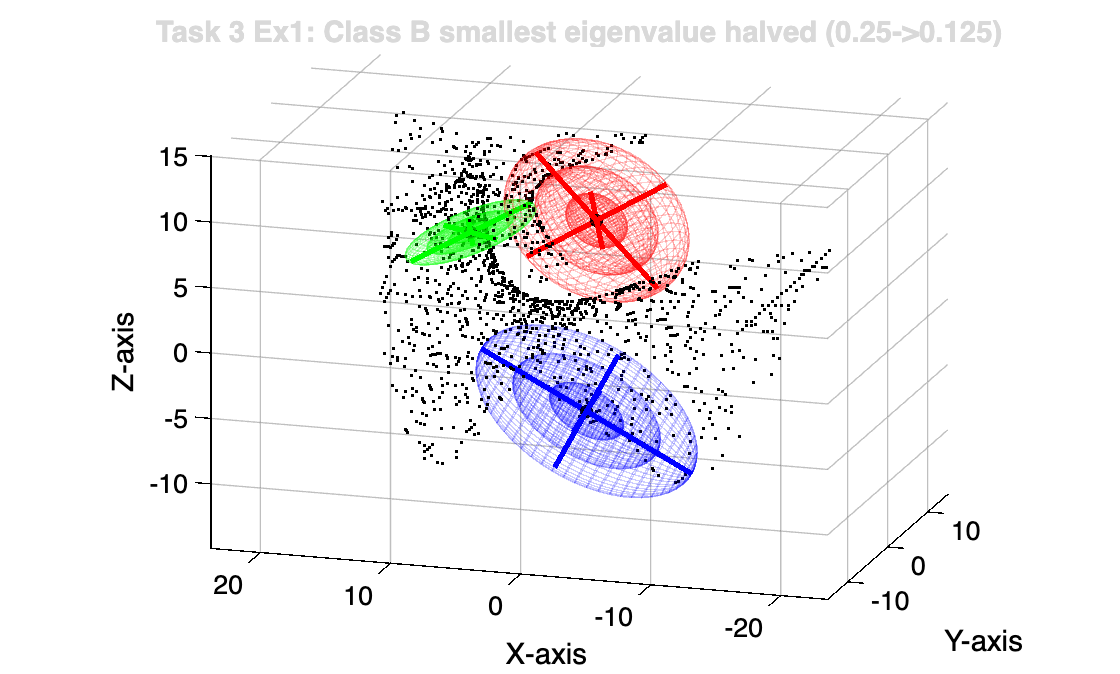


plotScenario(mu_a, covm_a, mu_b, covm_b_ex1, mu_c, covm_c, ...
    'Task 3 Ex1: Class B smallest eigenvalue halved (0.25->0.125)', Vaxis, Num);


% Example 2: scale covm_a by 1.3 (30% increase)
covm_a_ex2 = covm_a * 1.3;

fprintf('Example 2: covm_a scaled by 1.3 (30%% increase)\n');

Example 2: covm_a scaled by 1.3 (30% increase)


fprintf('  A and C share eigenvalue magnitudes (1,4,9) - small symmetry break -> large boundary shift\n\n');

  A and C share eigenvalue magnitudes (1,4,9) - small symmetry break -> large boundary shift



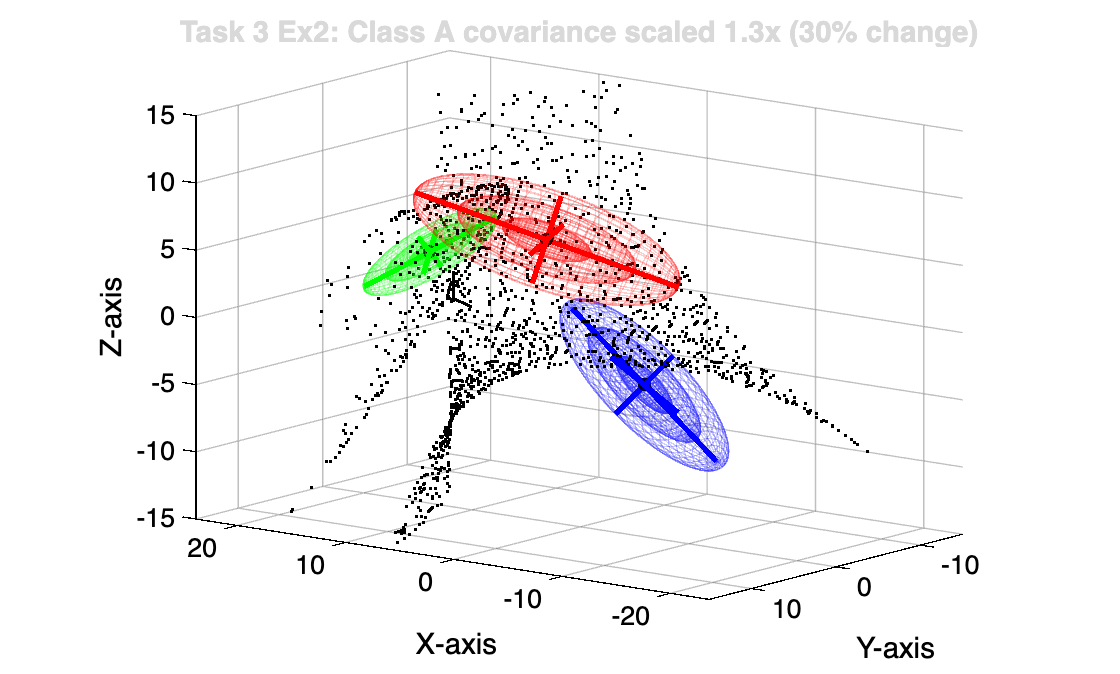


plotScenario(mu_a, covm_a_ex2, mu_b, covm_b, mu_c, covm_c, ...
    'Task 3 Ex2: Class A covariance scaled 1.3x (30% change)', Vaxis, Num);